clear

syms psi_t(t) theta_t(t) phi_t(t) psi theta phi psi_dot theta_dot phi_dot ...
    psi_dot_dot theta_dot_dot phi_dot_dot I I0 tau1 tau2 tau3 q_j

I_DD = diag([I,I,I0]);

R_X(q_j) = [1,0,0;0,cos(q_j),-sin(q_j);0,sin(q_j),cos(q_j)];
R_Y(q_j) = [cos(q_j),0,sin(q_j);0,1,0;-sin(q_j),0,cos(q_j)];
R_Z(q_j) = [cos(q_j),-sin(q_j),0;sin(q_j),cos(q_j),0;0,0,1];

R_NA = R_X(psi_t);
R_AB = R_Y(theta_t);
R_BD = R_Z(phi_t);

R_NB = R_NA*R_AB;
R_ND = R_NB*R_BD;

M_net = [tau1;0;0] + R_NA*[0;tau2;0] + R_NB*[0;0;tau3];

H_net = R_ND*I_DD*R_ND.'*([diff(psi_t,t);0;0] + R_NA*[0;diff(theta_t,t);0] + R_NB*[0;0;diff(phi_t,t)]);

H_net_dot = diff(H_net,t);

ang_accel_t = [diff(psi_t,t,t);diff(theta_t,t,t);diff(phi_t,t,t)];
ang_accel = [psi_dot_dot;theta_dot_dot;phi_dot_dot];

ang_vel_t = [diff(psi_t,t);diff(theta_t,t);diff(phi_t,t)];
ang_vel = [psi_dot;theta_dot;phi_dot];

ang_t = [psi_t;theta_t;phi_t];
ang = [psi;theta;phi];

H_net_dot = subs(H_net_dot,[ang_accel_t;ang_vel_t;ang_t],[ang_accel;ang_vel;ang]);

temp = jacobian(H_net_dot,ang_accel);

temp_inv = inv(temp);

rem = subs(H_net_dot,ang_accel,[0;0;0]);

ang_dot_dot = temp_inv*(M_net-rem);

state_dot = [ang_dot_dot;psi_dot;theta_dot;phi_dot];

state_dot = subs(state_dot,[ang_accel_t;ang_vel_t;ang_t],[ang_accel;ang_vel;ang]);

state = [psi_dot;theta_dot;phi_dot;psi;theta;phi];
input = [tau1;tau2;tau3];

B = jacobian(state_dot,input);
A = jacobian(state_dot,state);

state_e = [0;0;0;pi/2;0;87];
input_e = [0;0;0];

A = subs(A,[state;input],[state_e;input_e]);
B = subs(B,[state;input],[state_e;input_e]);

% defining the control matrices Q and R to compute the LQR gain
Q=0.001*eye(6);
R=0.001*eye(3);
% substituting values of moments of inertia in A and B and converting to
% double 
A_fun=formula(A);
B_fun=formula(B);
B_LQR=subs(B_fun,{I,I0},{0.00284584,0.00563843});
A_LQR=subs(A_fun,{I,I0},{0.00284584,0.00563843});
A_LQR=double(A_LQR);
B_LQR=double(B_LQR);
% checking controllability of the system
C = ctrb(A_LQR,B_LQR);
if rank(C) == length(A_LQR) 
    disp('The system is controllable')
else 
    disp('The system is NOT controllable')
    disp('Rank of the controllability matrix is:')
    rank(C)
end

The system is controllable


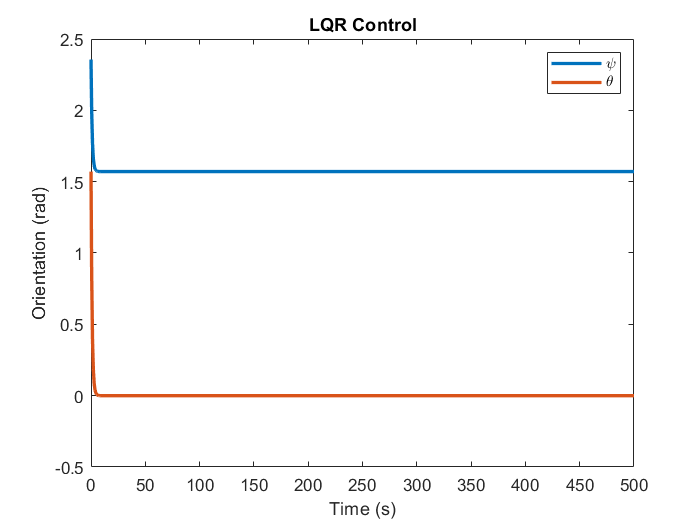

% computing the LQR gain
K=lqr(A_LQR,B_LQR,Q,R);

% specifiying initial state of system
state_initial = [0;0;0;3/4*pi;pi/2;0];
% specifying time period and time steps for the simulation 
tspan=0:0.01:500;

% simulating the closed loop response
% a - state 
[t,a] = ode45(@(t,a)((A_LQR-B_LQR*K)*(a-state_e)),tspan,state_initial);

% plotting variation of psi and theta
figure
plot(t,a(:,4:5),'LineWidth',2)
hold on
title("LQR Control")
legend('$\psi$','$\theta$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('Orientation (rad)')
hold off

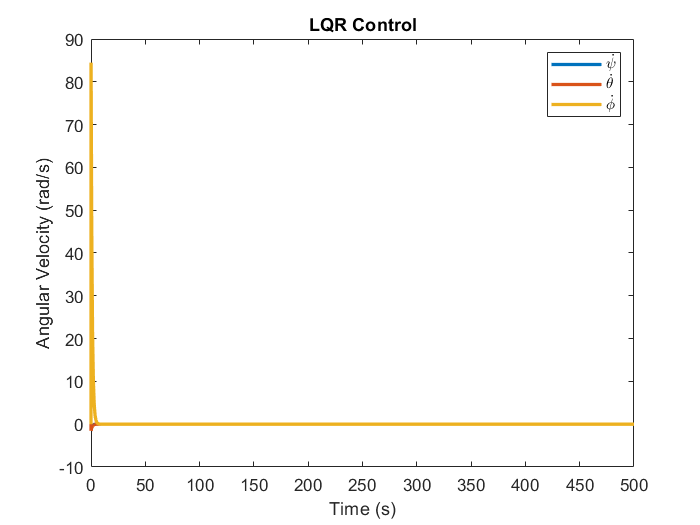


% plotting variation of angular velocities
figure 
plot(t,a(:,1:3),'LineWidth',2)
hold on
title("LQR Control")
legend('$\dot{\psi}$','$\dot{\theta}$','$\dot{\phi}$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')
hold off

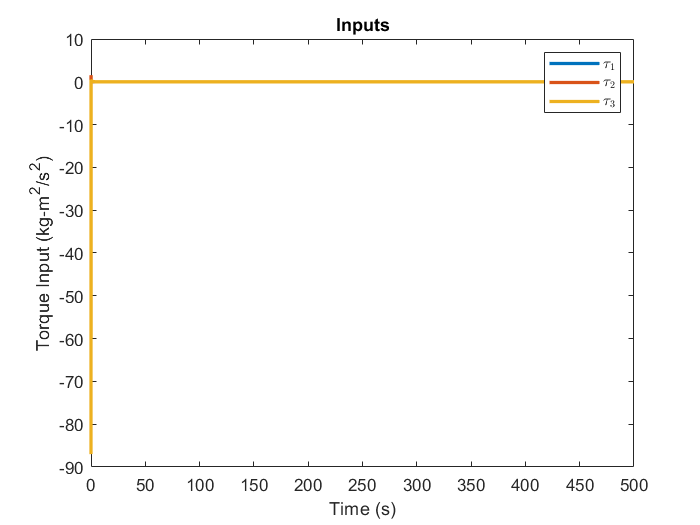


% plotting input over time 
figure
plot(t,(K*a'-K*state_e),'LineWidth',2)
hold on
title("Inputs")
legend('$\tau_1$','$\tau_2$', '$\tau_3$', 'interpreter','latex' )
xlabel('Time (s)')
ylabel('Torque Input (kg-m^2/s^2)')
hold off